close("all"); clear; clc;
addpath("prydeMotorcycleStateSpace\");

## Parameters

### Sharp model parameters

Cdelta = 6.77;
Cf1 = 11174;
Cf2 = 938.6;
Cr1 = 15831;
Cr2 = 1325.6;
Ibxx = 31.18;
Ibxz = -1.7355;
Ibzz = 21.07;
Ihxx = 1.2338;
Ihzz = 0.442;
v = 130/3.6;
a = 0.9485376;
an = 0.1158;
b = 0.4798;
e = 0.0244;
f = 0.0283;
g = 9.80665;
h = 0.6157;
ify = 0.7186;
iry = 1.0508;
mb = 217.45;
mh = 30.65;
rf = 0.3048;
rr = 0.3048;
tf = 0.0;
tr = 0.0;
caster = 0.4715;

### Center of mass

Ob = [b,0,h].';
Oa = [b,0,0].';
Ry = roty(rad2deg(-caster));
Oh = Oa + Ry*[a,0,0].';
m = mb + mh;
G = (mb.*Ob + mh.*Oh)./m;

### Normal forces

l = (a - an)/cos(caster);
p = b + l;
Zr = m*g*(p - G(3))/p;
Zf = m*g*G(3)/p;

### Tire coefficients

Longitudinal :

kkf = 20;
kkr = 20;

Lateral :

kaf = Cf1/Zf;
klf = Cf2/Zf;
kar = Cr1/Zr;
klr = Cr2/Zr;

### Pryde parameters

params = [
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    an;
    b;
    e;
    f;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    mb;
    mh;
    rf;
    rr;
    tf;
    tr;
    caster
    ];

sys = prydeMotorcycleStateSpace(params);
sys.StateName = [
    "phi";
    "delta";
    "omega_bz";
    "v_rx";
    "v_ry";
    
    ];

eig(sys.a)

ans = 1.0e+02 *

  -0.0685 + 1.1135i
  -0.0685 - 1.1135i
  -0.2567 + 0.1459i
  -0.2567 - 0.1459i
   0.0815 + 0.1283i
   0.0815 - 0.1283i
  -0.6483 + 0.0000i
  -0.7196 + 0.0000i
   0.0000 + 0.0000i


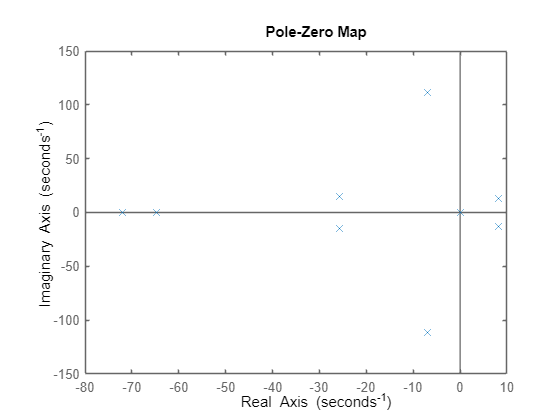

pzmap(sys)

rmpath("prydeMotorcycleStateSpace\")